# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgm.mlx
    ---------------
    This code solves the stochastic growth model using value function iteration.

%}

## Model: Stochastic Growth Model.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t + i_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints hold for $t = 1, 2, ...,$. The rationale for the constraints that are similar to those in the deterministic growth model. The productivity term, $A_t$, is a stationary AR(1) in logs by assumption, but is based on empirical literature. This stochastic process is what the conditional expectations operator, $\mathbb{E}_0(\cdot)$, is applied to.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t,A_t) = \underset{c_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha} =  c_t + k_{t+1} - (1-\delta)k_t \end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ .$$



$$c_t > 0,  k_t > 0 \text{ .}$$


Because of the productivity shocks, the state space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$k_t > 0 \ ,$$


simplifying the problem as before.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/apple/Downloads/ps1 /'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is /Users/apple/Downloads/ps1 / 



## Set the parameters and generate the state space.

Calls: model.m.

We cannot directly compute the steady state capital as before because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

As in the deterministic case, we will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left(A_tk_t^{\alpha}-(1-\delta)k_t\right)^{1-\sigma}}{1-\sigma} \ ,$$


as a guess.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 264 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 6.1100 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the deterministic growth model. The difference now is that because there are different levels of productivity, there will be a separate function for each level. For example, the seven production functions correspond to different levels of $A_t$. The blue line is production at the lowest level of $A_t$ while the red line is production at the highest level. The general pattern is that the higher $A_t$ is, the more resources there are for consumption, saving, and investment.

Because of productivity fluctuations, there is not a deterministic steady state level. Instead, the variables co-move with the productivity shocks. When productivity is low, output, consumption, and investment are low. Similarly, these variables are high when there are high productivity shocks. Utility in each period fluctuates with consumption.

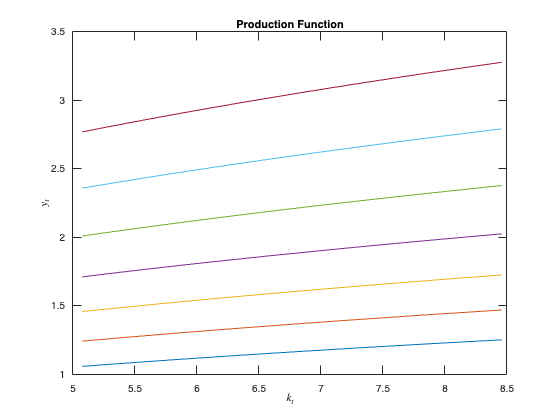

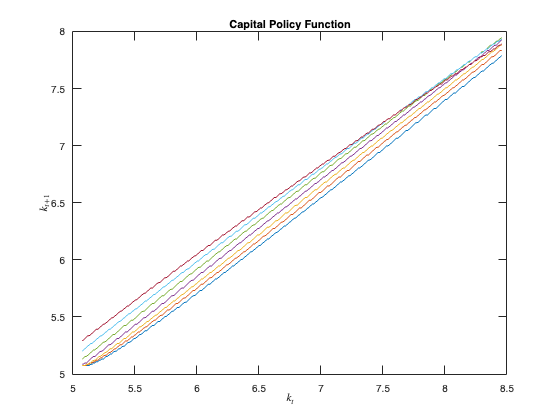

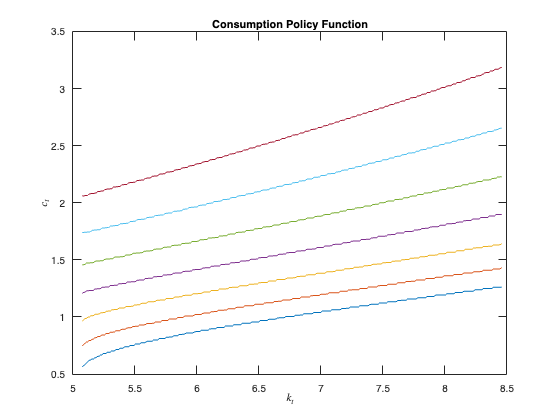

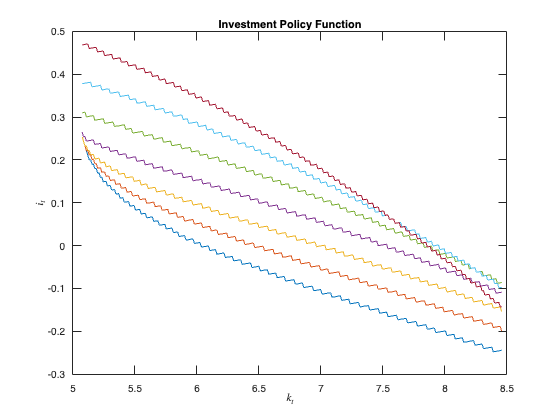

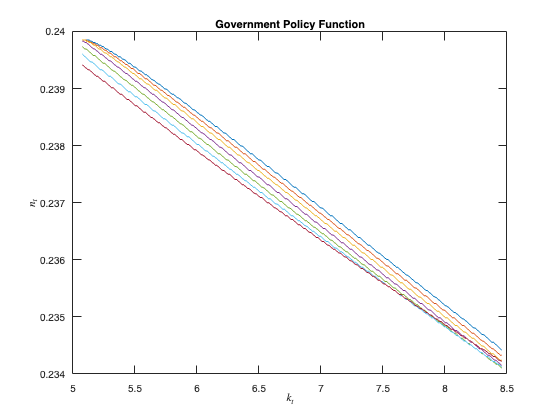

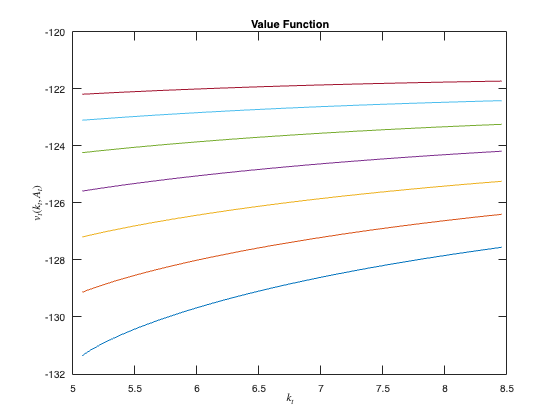

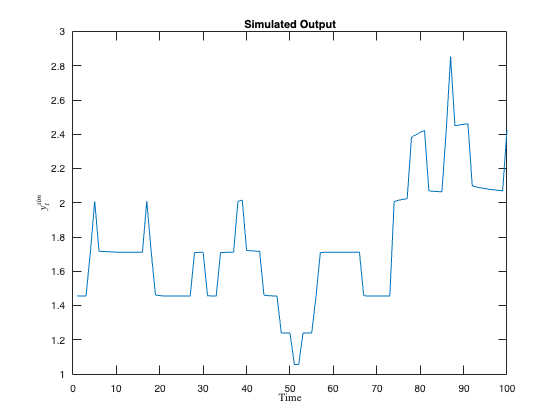

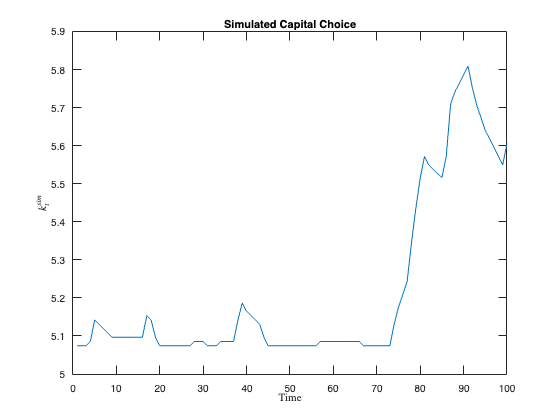

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.df = 

%% Define Tax Variations and Initialize Arrays

tau_k_values = [0.15, 0.20, 0.25]; % Different capital tax rates
num_scenarios = length(tau_k_values);
T_sim = par.T; % Total simulation periods

% Preallocate matrices for output, consumption, investment, and capital
ysim_data = zeros(num_scenarios, T_sim);
csim_data = zeros(num_scenarios, T_sim);
isim_data = zeros(num_scenarios, T_sim);
ksim_data = zeros(num_scenarios, T_sim);

%% Loop Over Different tau_k Values and Store Results

for i = 1:num_scenarios
    % Set up model parameters
    par = model.setup; % Reset parameters
    par.tau_k = tau_k_values(i); % Set different capital tax rates
    par = model.gen_grids(par); % Generate state space
    
    % Solve and simulate model
    sol = solve.grow(par);
    sim = simulate.grow(par, sol);

    % Store results in matrices
    ysim_data(i, :) = sim.ysim';
    csim_data(i, :) = sim.csim';
    isim_data(i, :) = sim.isim';
    ksim_data(i, :) = sim.ksim';
end

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.

Converged in 299 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 264 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.

Converged in 200 iterations.

------------End of Value Function Iteration.------------


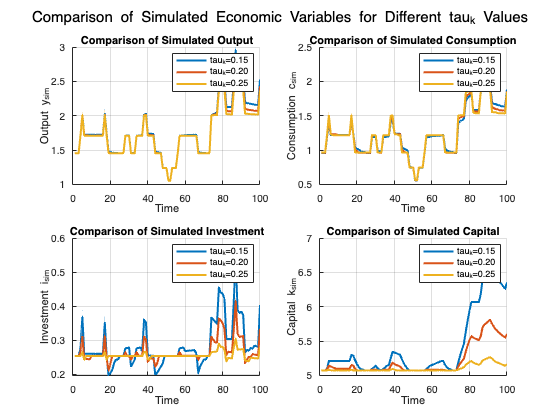


%% Plot Results

figure;

% Plot Output Comparison
subplot(2,2,1);
hold on;
for i = 1:num_scenarios
    plot(1:T_sim, ysim_data(i, :), 'LineWidth', 2, ...
         'DisplayName', sprintf('tau_k=%.2f', tau_k_values(i)));
end
title('Comparison of Simulated Output');
xlabel('Time');
ylabel('Output y_{sim}');
grid on;
legend show;

% Plot Consumption Comparison
subplot(2,2,2);
hold on;
for i = 1:num_scenarios
    plot(1:T_sim, csim_data(i, :), 'LineWidth', 2, ...
         'DisplayName', sprintf('tau_k=%.2f', tau_k_values(i)));
end
title('Comparison of Simulated Consumption');
xlabel('Time');
ylabel('Consumption c_{sim}');
grid on;
legend show;

% Plot Investment Comparison
subplot(2,2,3);
hold on;
for i = 1:num_scenarios
    plot(1:T_sim, isim_data(i, :), 'LineWidth', 2, ...
         'DisplayName', sprintf('tau_k=%.2f', tau_k_values(i)));
end
title('Comparison of Simulated Investment');
xlabel('Time');
ylabel('Investment i_{sim}');
grid on;
legend show;

% Plot Capital Comparison
subplot(2,2,4);
hold on;
for i = 1:num_scenarios
    plot(1:T_sim, ksim_data(i, :), 'LineWidth', 2, ...
         'DisplayName', sprintf('tau_k=%.2f', tau_k_values(i)));
end
title('Comparison of Simulated Capital');
xlabel('Time');
ylabel('Capital k_{sim}');
grid on;
legend show;

sgtitle('Comparison of Simulated Economic Variables for Different tau_k Values');


% Save figure
fig_name = strcat(figout, 'tau_k_comparison.fig');
savefig(fig_name);
%% Generate Descriptive Statistics Table for Different tau_k Values

% Define tax rate variations
tau_k_values = [0.15, 0.20, 0.25]; % Capital tax rates
num_scenarios = length(tau_k_values);
T_sim = par.T; % Total simulation periods

% Preallocate matrices for storage
gov_data = zeros(num_scenarios, T_sim);
gdp_data = zeros(num_scenarios, T_sim);
investment_data = zeros(num_scenarios, T_sim);
consumption_data = zeros(num_scenarios, T_sim);

%% Loop Over Different tau_k Values and Store Results
for i = 1:num_scenarios
    % Set up model parameters
    par = model.setup; % Reset parameters
    par.tau_k = tau_k_values(i); % Modify capital tax rate
    par = model.gen_grids(par); % Generate state space
    
    % Solve and simulate model
    sol = solve.grow(par);
    sim = simulate.grow(par, sol);

    % Store results
    gov_data(i, :) = sim.gsim';
    gdp_data(i, :) = sim.ysim';
    investment_data(i, :) = sim.isim';
    consumption_data(i, :) = sim.csim';
end

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.

Converged in 299 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 264 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.

Converged in 200 iterations.

------------End of Value Function Iteration.------------



%% Compute Descriptive Statistics
stats = @(data) [mean(data, 2), std(data, 0, 2), min(data, [], 2), max(data, [], 2)];

gov_stats = stats(gov_data);
gdp_stats = stats(gdp_data);
investment_stats = stats(investment_data);
consumption_stats = stats(consumption_data);

% Create Table
VarNames = {'Mean', 'Std Dev', 'Min', 'Max'};
RowNames = arrayfun(@(x) sprintf('tau_k=%.2f', x), tau_k_values, 'UniformOutput', false);

DescriptiveTable = table(gov_stats, gdp_stats, investment_stats, consumption_stats, ...
    'VariableNames', {'Government', 'GDP', 'Investment', 'Consumption'}, ...
    'RowNames', RowNames);

% Display Table
disp(DescriptiveTable);

                                     Government                                          GDP                                      Investment                                   Consumption              
                  _________________________________________________    _______________________________________    ___________________________________________    _______________________________________

    tau_k=0.15    0.24188     0.0007343       0.24005       0.24239     1.776    0.38312     1.0557     2.9534    0.28289    0.061702     0.19657     0.53542    1.2512    0.33384     0.5596     2.1776
    tau_k=0.20    0.23957    0.00045442       0.23838       0.23985    1.7525    0.35635     1.0557     2.8537    0.26581    0.032367     0.21185     0.41436    1.2471    0.33323    0.56214     2.2008
    tau_k=0.25


% Save Table to CSV
writetable(DescriptiveTable, strcat(figout, 'descriptive_stats.csv'), 'WriteRowNames', true);



filename = 'dataps5.xlsx';
T = readtable(filename);

disp(T)

    VietNam    LabourForceAt15YearsOfAgeAndAboveByProvince___ByCities_Provinci    NumberOfNewlyEstablishedEnterprisesByProvinceByCities_Provincie       GDP        FDI_NetInflows_BoP_CurrentUS__    GDPPerPersonEmployed    GDPGrowthRate    consumption    invesment_Capita
    _______    _______________________________________________________________    _______________________________________________________________    __________    ______________________________    ____________________    _____________    ___________    ________________

     1996                                     NaN                                                                NaN                                 2.46

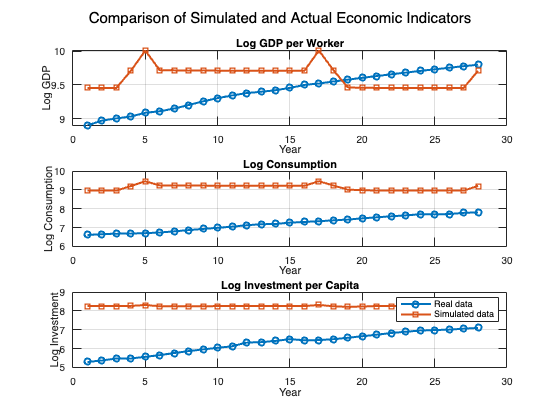

% Extract first 28 data points
T_extract = 28;

Asim_28 = sim.Asim(1:T_extract);
ysim_28 = sim.ysim(1:T_extract);
ksim_28 = sim.ksim(1:T_extract);
csim_28 = sim.csim(1:T_extract);
gsim_28 = sim.gsim(1:T_extract);
isim_28 = sim.isim(1:T_extract);
usim_28 = sim.usim(1:T_extract);

%% Compute Logarithm
log_GDP_per_worker = log(T.GDPPerPersonEmployed);
log_Consumption = log(T.consumption);
log_Investment_per_capita = log(T.invesment_Capita);

%% Time Vector
years = 1:length(T.VietNam); % Extract first 28 years

%% Plot Comparison
figure;

% Plot Log GDP per Worker
subplot(3,1,1);
plot(years, log_GDP_per_worker, 'o-', 'LineWidth', 2, 'DisplayName', 'Actual');
hold on;
plot(years, 8 + ysim_28, 's-', 'LineWidth', 2, 'DisplayName', 'Simulated');
title('Log GDP per Worker');
xlabel('Year');
ylabel('Log GDP');
grid on;

% Plot Log Consumption
subplot(3,1,2);
plot(years, log_Consumption, 'o-', 'LineWidth', 2, 'DisplayName', 'Actual');
hold on;
plot(years, 8 + csim_28, 's-', 'LineWidth', 2, 'DisplayName', 'Simulated');
title('Log Consumption');
xlabel('Year');
ylabel('Log Consumption');
grid on;

% Plot Log Investment per Capita
subplot(3,1,3);
plot(years, log_Investment_per_capita, 'o-', 'LineWidth', 2, 'DisplayName', 'Actual');
hold on;
plot(years, 8 + isim_28, 's-', 'LineWidth', 2, 'DisplayName', 'Simulated');
title('Log Investment per Capita');
xlabel('Year');
ylabel('Log Investment');
legend('Real data', 'Simulated data');
grid on;

sgtitle('Comparison of Simulated and Actual Economic Indicators');